# Task2

Load the images

house_left = imread("../left.jpg");
house_right = imread("../right.jpg");

notr_dame_left = im2gray(imread("../notre_dame1.jpg"));
notr_dame_right = im2gray(imread("../notre_dame2.jpg"));

#### Compute the sift features for each picture

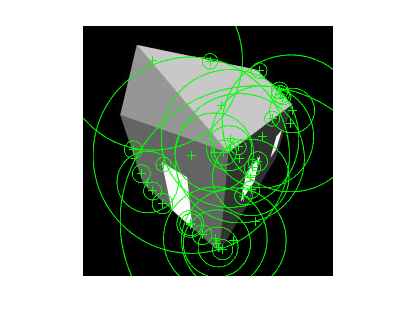

sift_left = detectSIFTFeatures(house_left);
sift_right = detectSIFTFeatures(house_right);

imshow(house_left)
hold on
plot(sift_left);
hold off

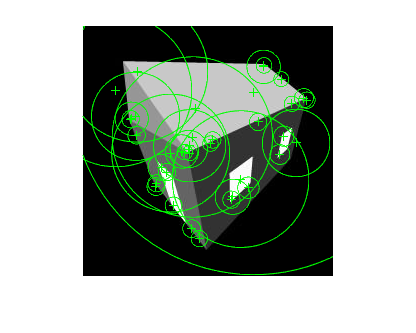

imshow(house_right)
hold on
plot(sift_right);
hold off

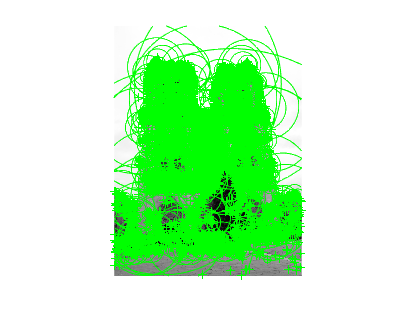

notre_dame_sift_1 = detectSIFTFeatures(notr_dame_left,"ContrastThreshold",.0266);
notre_dame_sift_2 = detectSIFTFeatures(notr_dame_right,"ContrastThreshold",.0266);

imshow(notr_dame_left)
hold on
plot(notre_dame_sift_1);
hold off

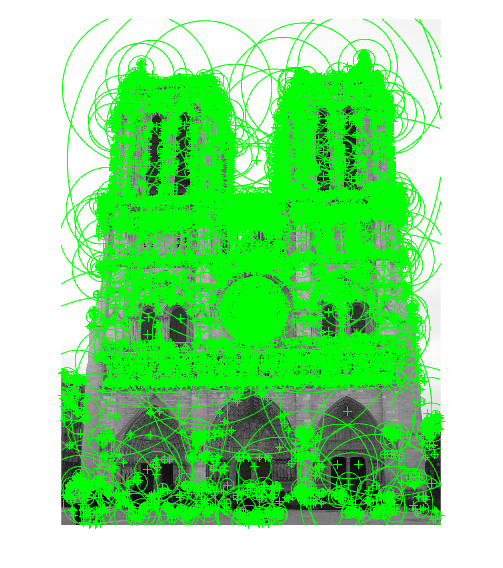

figure
imshow(notr_dame_right)
hold on
plot(notre_dame_sift_2);
hold off

figure

The SIFT features found on the house are some times on "flat" areas, where the image does not contain a lot of shape information, this is not ideal for rotation invariance. We can see that in the image of notredame the sift detector produces a lot of intrest points, but it seems to only grab the building which is benificial.

We can see that there are a lot of corners not detected by the SIFT detector, and there are a lot of corners detected in one image of the house and not in the other. This is bad for feature matching.

#### Compute Harris features for each of the pictures

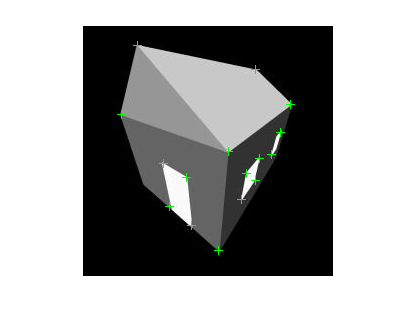

harris_left = detectHarrisFeatures(house_left);
harris_right = detectHarrisFeatures(house_right);

imshow(house_left)
hold on
plot(harris_left);
hold off

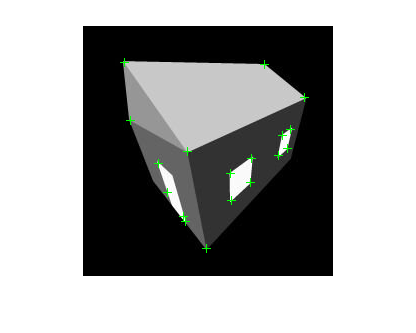

imshow(house_right)
hold on
plot(harris_right);
hold off

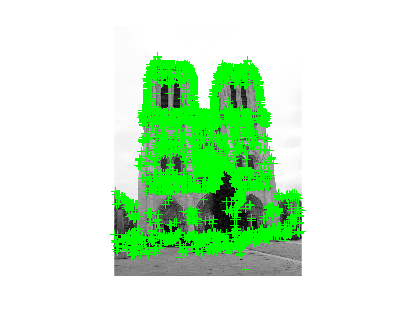

notre_dame_harris_1 = detectHarrisFeatures(notr_dame_left);
notre_dame_harris_2 = detectHarrisFeatures(notr_dame_right);

imshow(notr_dame_left)
hold on
plot(notre_dame_harris_1);
hold off

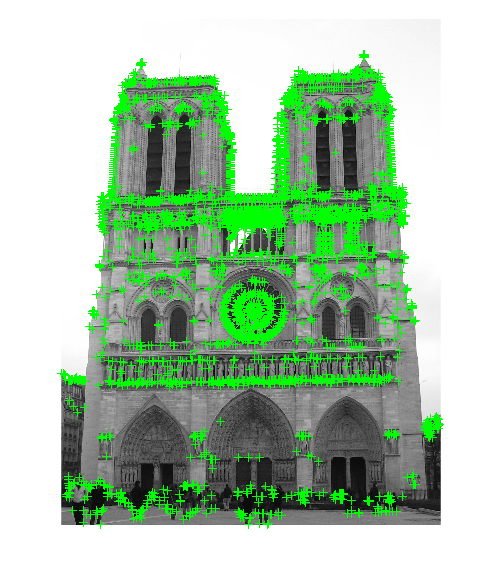

figure
imshow(notr_dame_right)
hold on
plot(notre_dame_harris_2);
hold off

figure

Here we can see that the harris detector only detects conrerns of the house, this is great for scale and rotation invariance since the corners will always have a large gradiant in all directions. We can also see that the harris detector detects a lot of corners and edges in the notredame image, this is ok but the result could be improved by thresholding the image a bit higher thus removing more of the lines from the image.

It is worth noting that the spires on the towers of notredame are detected in both of the angles using the harris detector. 

When looking at the house we can see that the only corner that differs in the two angles is the top right corner of the house.

#### Now do feature matching

I will use built in matlab functions for this since it is allowed.

### Matching harris features

- House

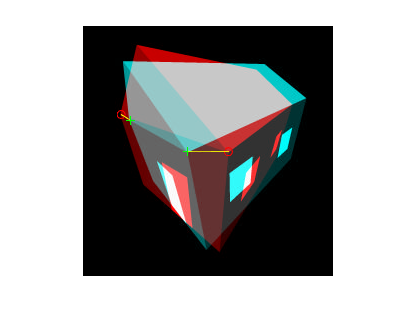

[features1,locations1] = extractFeatures(house_left,harris_left,"BlockSize",23);
[features2,locations2] = extractFeatures(house_right,harris_right,"BlockSize",23);
matched_features = matchFeatures(features1,features2);
showMatchedFeatures(house_left,house_right,locations1(matched_features(:,1),:),locations2(matched_features(:,2),:));

figure

Only 2 points kept, but they do accuratly depict the rotation and movement of the house.

- Notre damme

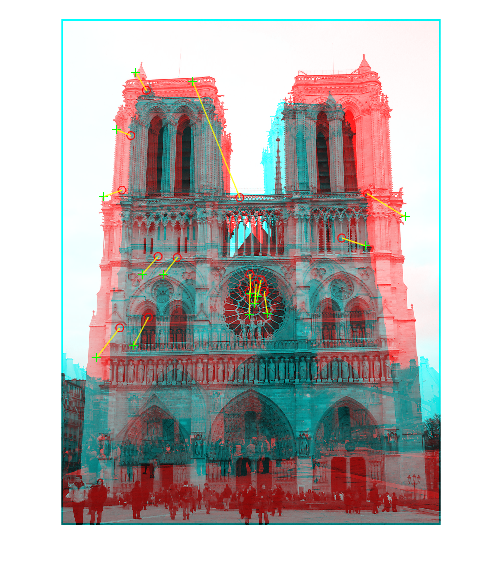

[features1,locations1] = extractFeatures(notr_dame_left,notre_dame_harris_1);
[features2,locations2] = extractFeatures(notr_dame_right,notre_dame_harris_2);
matched_features = matchFeatures(features1,features2);
showMatchedFeatures(notr_dame_left,notr_dame_right,locations1(matched_features(:,1),:),locations2(matched_features(:,2),:));

figure

There seems to be quite a few points removed by the process. But the points picked out seem to be mostly accurate, only one false positive, the one going from the top of the left tower down to the middle part.

### Matching SIFT features

- House

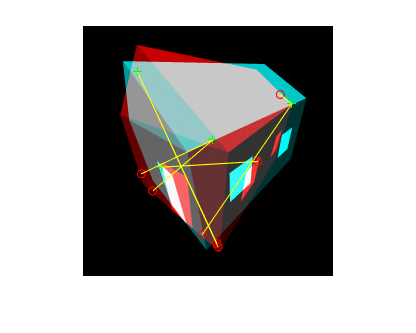

[features1,locations1] = extractFeatures(house_left,sift_left,"Method","SIFT");
[features2,locations2] = extractFeatures(house_right,sift_right,"Method","SIFT");
matched_features = matchFeatures(features1,features2);
showMatchedFeatures(house_left,house_right,locations1(matched_features(:,1),:),locations2(matched_features(:,2),:));

figure

We can see that the SIFT matching mainly provides false positives on the house.

- Notre damme

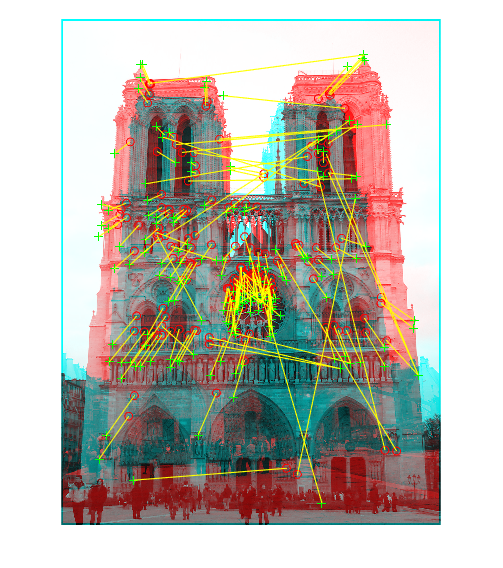

[features1,locations1] = extractFeatures(notr_dame_left,notre_dame_sift_1,"Method","SIFT");
[features2,locations2] = extractFeatures(notr_dame_right,notre_dame_sift_2,"Method","SIFT");
matched_features = matchFeatures(features1,features2);
showMatchedFeatures(notr_dame_left,notr_dame_right,locations1(matched_features(:,1),:),locations2(matched_features(:,2),:));

figure

Here the SIFT is better than the harris detector by quite a lot. There are a few false positives but it is still acceptable.

It seems that harris detectors work better on images that have lower "information density" i.e. where the images have less texture, and the SIFT detector works better on images with more texture.